%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Course :	Multimedia Data Security (2016)
% Project: 	Spread Spectrum
%           Watermark Embedding
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
close all; clear all;

## Read original image

I    = imread('lena.tif','tif');
[dimx,dimy] = size(I);
Id   = double(I);

## Generate random watermark

rng(6);
nValues=1024;
div=50000;
w = round(rand(1,nValues));
save('watermark','w');

## Define watermark strenght

alpha = 4;

## DCT transform

It = dct2(Id);
It_re = reshape(It,1,dimx*dimy);

## Modulo and sign

It_sgn = sign(It_re);
It_mod = abs(It_re);

## Modulo sorting

[It_sort,Ix] = sort(It_mod,'descend');

## Embedding

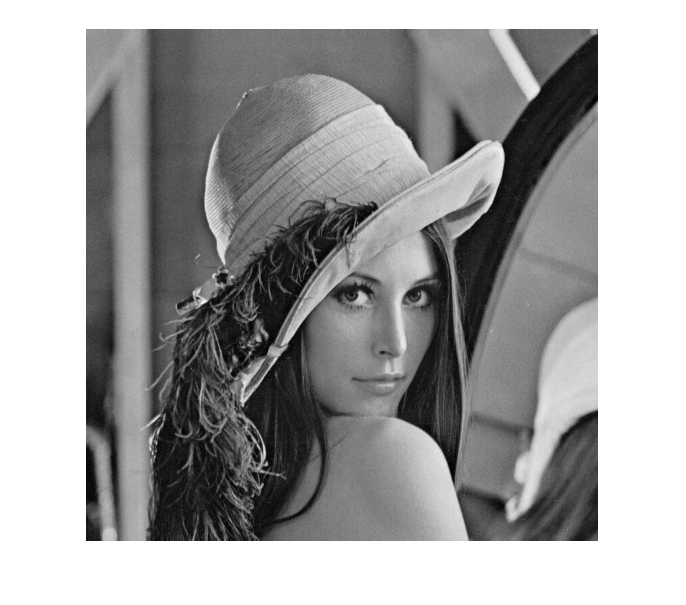

Itw_mod = It_mod; 
kfin=0;
min=100;
max=0;
k = 2;
for f=1:2000
    k=47000+(5*f);
    Itw_mod = It_mod; 
    for j = 2:nValues
        m = Ix(k);
        Itw_mod(m) = It_mod(m)*(1+alpha*w(j));
    %     Itw_mod(m) = It_mod(m)*exp(alpha*w(j));
        k = k+1;
     % k=round(k+(div/(k-1)));
        if(j==1)
            k=50000;
        end
    end
    % recover sign
    It_new = Itw_mod.*It_sgn;
    
    %watermark, from vector to matrix
    It_newi=reshape(It_new,dimx,dimy);
    %inverse dct
    I_inv = idct2(It_newi);
    wpsnr=WPSNR(uint8(I_inv),uint8(Id));
    if(wpsnr>max)
        max=wpsnr;
    end
    if(wpsnr>=62)
        if(wpsnr<min)
            min=wpsnr;
            kfin=40000+(5*f);
            break;
        end
    end
end 

k=kfin;
    for j = 2:nValues
        m = Ix(k);
        Itw_mod(m) = It_mod(m)*(1+alpha*w(j));
    %     Itw_mod(m) = It_mod(m)*exp(alpha*w(j));
        k = k+1;
     % k=round(k+(div/(k-1)));
        if(j==1)
            k=50000;
        end
    end
% recover sign
    It_new = Itw_mod.*It_sgn;
    
    %watermark, from vector to matrix
    It_newi=reshape(It_new,dimx,dimy);
    %inverse dct
    I_inv = idct2(It_newi);

imshow(I_inv,[]);

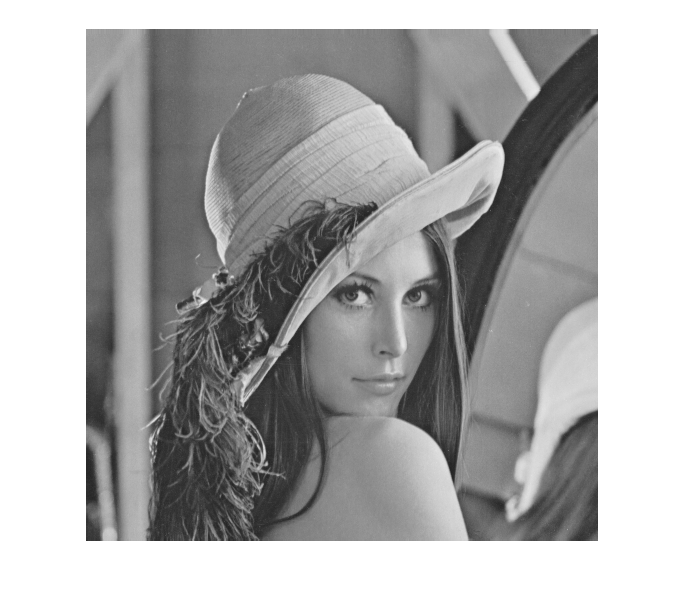

figure(); imshow(I);


%save watermarked image
imwrite(uint8(I_inv),'SSwat.tif','tif'); 
 
PSNR(uint8(I_inv),uint8(Id)) 

PSNR = +45.07 dB


wpsnr=WPSNR(uint8(I_inv),uint8(Id))

wpsnr = 59.1000